# FINDBESTK

Try to determine the best number of clusters for the basketball statistics.

## Load data

load bbstats

## Make silhouette plots for different numbers of clusters

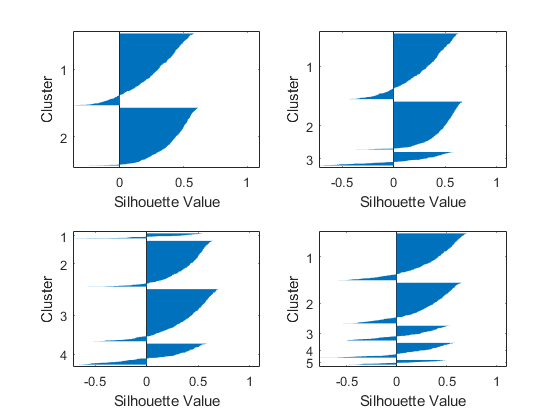

for k = 1:4
    subplot(2,2,k)
    rng(1234)
    gm = fitgmdist(statsnorm,k+1,'Replicates',5,'RegularizationValue',0.02,'Options',statset('MaxIter',900));
    g = cluster(gm,statsnorm);
    silhouette(statsnorm,g)
end

## Automate with EVALCLUSTERS

figure

Use silhouette value

rng(1234)
ce = evalclusters(statsnorm,'gmdistribution','silhouette','KList',2:8)

ce =   SilhouetteEvaluation with properties:

    NumObservations: 1112
         InspectedK: [2 3 4 5 6 7 8]
    CriterionValues: [0.5903 0.1673 0.2181 0.2085 0.1862 0.1856 0.1600]
           OptimalK: 2


subplot(2,1,1)
plot(ce.InspectedK,ce.CriterionValues)
xlabel('Number of clusters')
ylabel('Silhouette value')

Use Calinski-Harabasz criterion value

rng(1234)
ce = evalclusters(statsnorm,'gmdistribution','CalinskiHarabasz','KList',2:8)

ce =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 1112
         InspectedK: [2 3 4 5 6 7 8]
    CriterionValues: [225.9989 109.6771 148.8106 151.9404 160.9300 152.8062 142.0065]
           OptimalK: 2


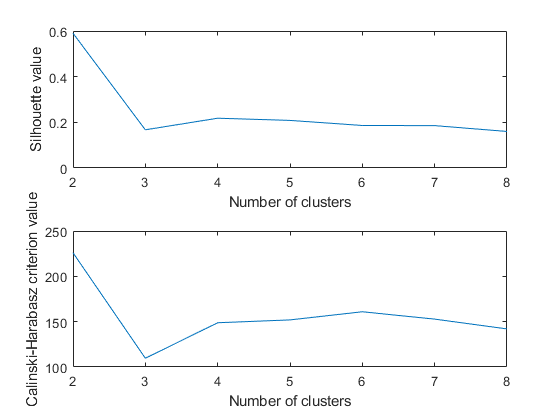

subplot(2,1,2)
plot(ce.InspectedK,ce.CriterionValues)
xlabel('Number of clusters')
ylabel('Calinski-Harabasz criterion value')